# Fórmulas de derivación numérica

## Introducción

En esta sección se expone el problema que se desea solucionar, así como  el objetivo a cumplir.  Además,  se  describe  la  organización  del  presente documento.

### Contexto

jaja no c si esto va

### Identificación del problema

esto si va pero no se cual es el problema

### Objetivo general

Explorar los errores que presentan diferentes fórmulas de derivación numérica: las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada, $O\left(h\right)$ y $O\left(h^2 \right)$. 

### Organización del documento

El documento está estructurado de la siguiente manera:

- **Sección 1: Introducción**. Se describe el contexto, el problema a resolver y el objetivo general del proyecto.

- **Sección 2: Análisis**. Se especifican los requerimientos funcionales y no funcionales de la solución, así como sus restricciones.

- **Sección 3: Desarrollo**. Se exponen detalladamente las funciones desarrolladas que pretenden cumplir con el objetivo del proyecto.

- **Sección 4: Pruebas y Resultados**. Se presentan las pruebas llevadas a cabo con el fin de evaluar el cumplimiento de los requerimientos y explorar los errores obtenidos de las funciones de aproximación.

- **Sección 5: Conclusiones**. Se evalúa el desempeño general del proyecto en relación con  el  objetivo  y  el  problema  a  resolver.  Además,  se  explican  posibles  mejoras  y propuestas de trabajos futuros para profundizar la solución.

## Análisis

En esta sección se describen las funcionalidades generales que debe cumplir la solución, así como las restricciones para su desarrollo.

### Requerimientos

#### Funcionales

- a ver digan otros 2 o 3 pls

- El sistema debe mostrar recursos gráficos para facilitar la evaluación de los errores.

#### No funcionales

- En caso de error, se debe informar al usuario de manera clara cuál fue dicho error.

- El código debe ser documentado adecuadamente siguiendo las convenciones de código (nombres de variables y funciones, sangría y espaciado, etc.)

### Restricciones

- supongo que aqui podriamos poner algo de qué funciones usaremos o no c

## Pruebas y resultados

blablabla

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -2.23750000000000 	  1.3250000000000
  0.1000000000 	 -1.00360000000000 	  0.0911000000000
  0.0100000000 	 -0.92128509999999 	  0.0087851000000
  0.0010000000 	 -0.91337535009994 	  0.0008753500999
  0.0001000000 	 -0.91258750349987 	  0.0000875034999
  0.0000100000 	 -0.91250875002835 	  0.0000087500284
  0.0000010000 	 -0.91250087497219 	  0.0000008749722
  0.0000001000 	 -0.91250008660282 	  0.0000000866028
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91249996447829 	  0.0000000355217
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


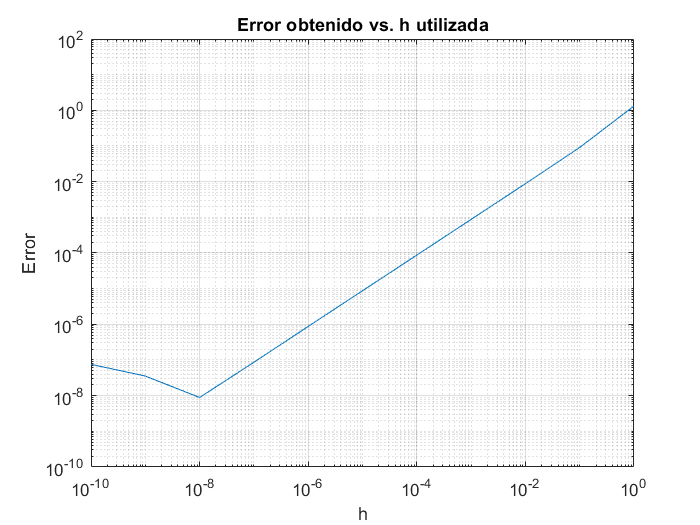

f = @(x) -0.1 * x.^4 - 0.15 * x.^3 - 0.5 * x.^2 - 0.25 * x + 1.2;
x = 0.5;
dfForward1(f, x);

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.38750000000000 	  1.3000000000000
  0.1000000000 	 -0.90490000000000 	  0.0076000000000
  0.0100000000 	 -0.91242939999998 	  0.0000706000000
  0.0010000000 	 -0.91249929939985 	  0.0000007006002
  0.0001000000 	 -0.91249999299992 	  0.0000000070001
  0.0000100000 	 -0.91249999991660 	  0.0000000000834
  0.0000010000 	 -0.91250000000542 	  0.0000000000054
  0.0000001000 	 -0.91249999778498 	  0.0000000022150
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91250007550059 	  0.0000000755006
  0.0000000001 	 -0.91250118572361 	  0.0000011857236


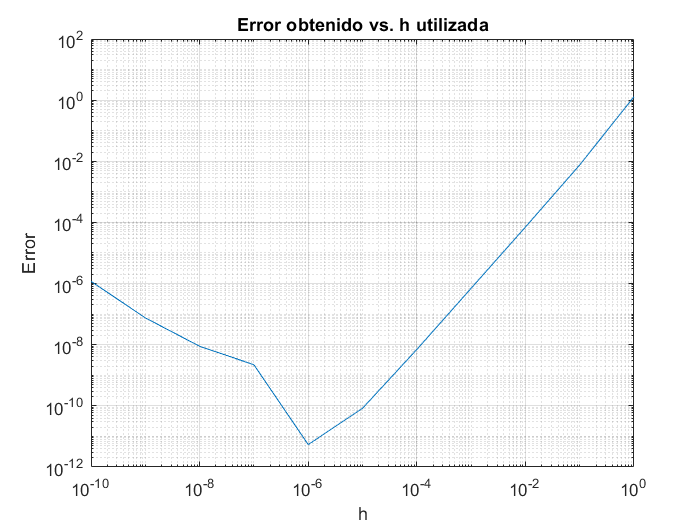

dfForward2(f, x);

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -1.26250000000000 	  0.3500000000000
  0.1000000000 	 -0.91600000000000 	  0.0035000000000
  0.0100000000 	 -0.91253500000000 	  0.0000350000000
  0.0010000000 	 -0.91250035000001 	  0.0000003500000
  0.0001000000 	 -0.91250000349985 	  0.0000000034998
  0.0000100000 	 -0.91250000003318 	  0.0000000000332
  0.0000010000 	 -0.91250000000542 	  0.0000000000054
  0.0000001000 	 -0.91249999945031 	  0.0000000005497
  0.0000000100 	 -0.91250000333609 	  0.0000000033361
  0.0000000010 	 -0.91250001998944 	  0.0000000199894
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


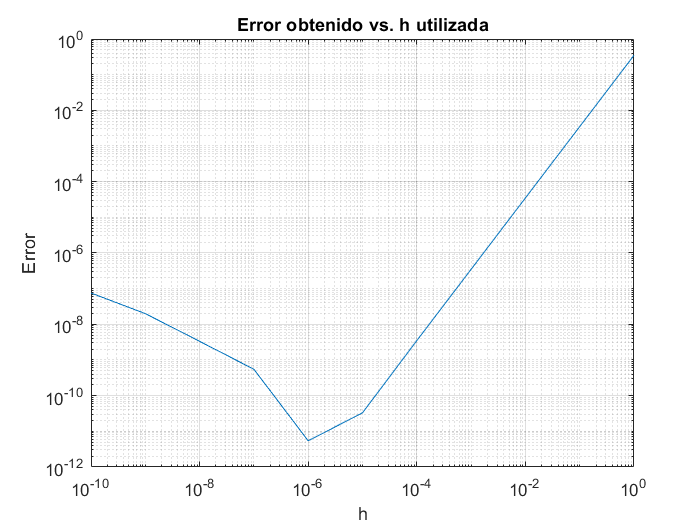

dfCentral(f, x);

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.28750000000000 	  0.6250000000000
  0.1000000000 	 -0.82840000000000 	  0.0841000000000
  0.0100000000 	 -0.90378490000000 	  0.0087151000000
  0.0010000000 	 -0.91162534990008 	  0.0008746500999
  0.0001000000 	 -0.91241250349983 	  0.0000874965002
  0.0000100000 	 -0.91249125003801 	  0.0000087499620
  0.0000010000 	 -0.91249912503866 	  0.0000008749613
  0.0000001000 	 -0.91249991229780 	  0.0000000877022
  0.0000000100 	 -0.91249999778498 	  0.0000000022150
  0.0000000010 	 -0.91250007550059 	  0.0000000755006
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


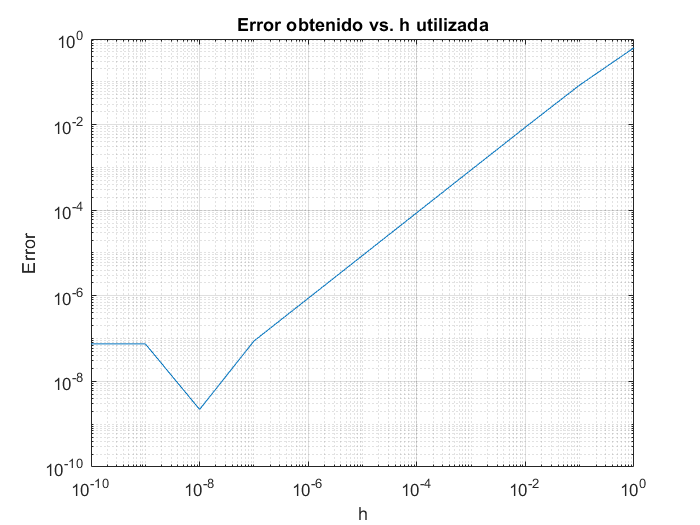

dfBackward1(f, x);

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.81250000000000 	  0.1000000000000
  0.1000000000 	 -0.90610000000000 	  0.0064000000000
  0.0100000000 	 -0.91243060000000 	  0.0000694000000
  0.0010000000 	 -0.91249930060011 	  0.0000006993999
  0.0001000000 	 -0.91249999299992 	  0.0000000070001
  0.0000100000 	 -0.91249999992771 	  0.0000000000723
  0.0000010000 	 -0.91250000000542 	  0.0000000000054
  0.0000001000 	 -0.91249999889520 	  0.0000000011048
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91250007550059 	  0.0000000755006
  0.0000000001 	 -0.91249952038908 	  0.0000004796109


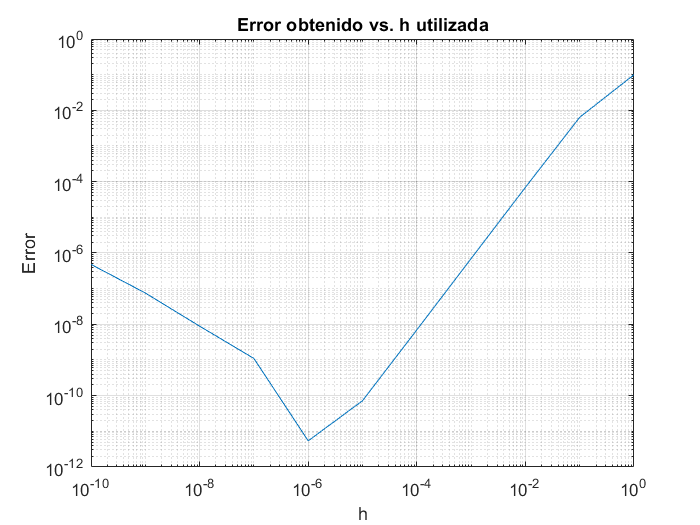

dfBackward2(f, x);

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -5.25000000000000 	  3.5000000000000
  0.1000000000 	 -1.97400000000002 	  0.2240000000000
  0.0100000000 	 -1.77114000000200 	  0.0211400000020
  0.0010000000 	 -1.75210140007653 	  0.0021014000765
  0.0001000000 	 -1.75021001025399 	  0.0002100102540
  0.0000100000 	 -1.75002234925614 	  0.0000223492561
  0.0000010000 	 -1.75004455371663 	  0.0000445537166
  0.0000001000 	 -1.76525460915400 	  0.0152546091540
  0.0000000100 	 -1.11022302462516 	  0.6397769753748
  0.0000000010 	 -111.02230246251560 	 109.2723024625156
  0.0000000001 	 0.00000000000000 	  1.7500000000000


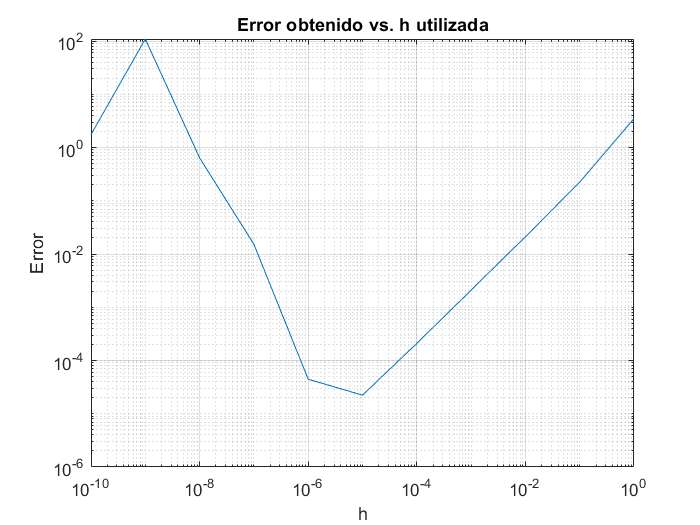

ddfForward1(f, x);

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.45000000000000 	  2.2000000000000
  0.1000000000 	 -1.72800000000011 	  0.0219999999999
  0.0100000000 	 -1.74978000000214 	  0.0002199999979
  0.0010000000 	 -1.74999779978258 	  0.0000022002174
  0.0001000000 	 -1.75000003377335 	  0.0000000337733
  0.0000100000 	 -1.75000236524170 	  0.0000023652417
  0.0000010000 	 -1.75037762062402 	  0.0003776206240
  0.0000001000 	 -1.75415237890775 	  0.0041523789077
  0.0000000100 	 2.22044604925031 	  3.9704460492503
  0.0000000010 	 -666.13381477509358 	 664.3838147750936
  0.0000000001 	 -22204.46049250311989 	 22202.7104925031199


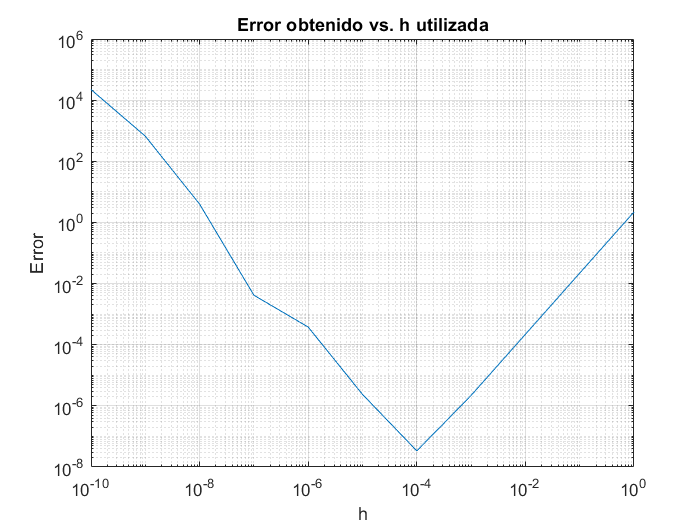

ddfForward2(f, x);

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -1.95000000000000 	  0.2000000000000
  0.1000000000 	 -1.75200000000000 	  0.0020000000000
  0.0100000000 	 -1.75001999999869 	  0.0000199999987
  0.0010000000 	 -1.75000019986271 	  0.0000001998627
  0.0001000000 	 -1.75000000046666 	  0.0000000004667
  0.0000100000 	 -1.74999903457262 	  0.0000009654274
  0.0000010000 	 -1.74993353141417 	  0.0000664685858
  0.0000001000 	 -1.74305014866149 	  0.0069498513385
  0.0000000100 	 -1.11022302462516 	  0.6397769753748
  0.0000000010 	 111.02230246251560 	 112.7723024625156
  0.0000000001 	 0.00000000000000 	  1.7500000000000


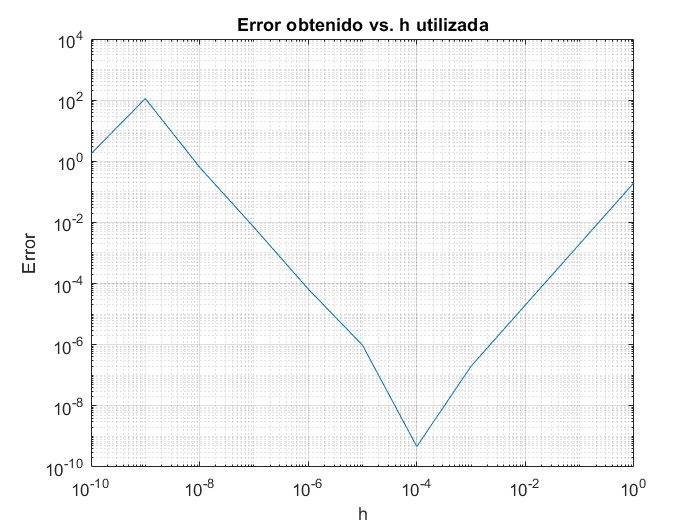

ddfCentral(f, x);

## Conclusiones

blablabla

## Referencias

blabla

## Anexo: Funciones

Se desarrollaron las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada; $O\left(h\right)$ y $O\left(h^2 \right)$. Es importante señalar que para las aproximaciones centradas, unicamente se presentan las correspondientes a $O\left(h^2 \right)$. Además, se implementaron métodos para imprimir los resultados obtenidos y desplegar la gráfica generada. Para cada función de aproximación, se codficó una versión más amigable al usuario que no regresa variables, sino que muestra dicha gráfica y valores calculados.

### Funciones auxiliares

function showResults(hs, aprxs, err)
% Imprime una tabla de las h generadas, su aproximación, y el error 
% correspondiente.
% Parámetros:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    format long
    res = [hs' aprxs' err']';
    fprintf('\t h \t     aproximación \t \t error\n');
    fprintf('%14.10f \t %16.14f \t %16.13f\n', res);
    format short
end


function plotError(hs, err)
% Despliega la gráfica correspondiente a las h generadas y sus errores 
% calculados, utiilizando la funcion loglog de MATLAB.
% Parámetros:
%    hs = las h utilizadas en las aproximaciones
%    err = los errores obtenidos

    loglog(hs, err)
    grid on
    title('Error obtenido vs. h utilizada')
    xlabel('h')
    ylabel('Error')
end

### Primera derivada

Para la primera derivada, se exponen las siguientes funciones:

- Aproximación hacia adelante: $O\left(h\right)$

- Aproximación hacia adelante: $O\left(h^2 \right)$

- Aproximación centrada: $O\left(h^2 \right)$

- Aproximación hacia atrás: $O\left(h\right)$

- Aproximación hacia atrás: $O\left(h^2 \right)$

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}$

function [hs, aprxs, err] = firstDerForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la primera
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - fx) / h;
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end



function dfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerForwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{-\frac{1}{2}f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}=\frac{-f\left(x+2h\right)+4f\left(x+h\right)-3f\left(x\right)}{2h}$

function [hs, aprxs, err] = firstDerForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la primera
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (-f(x + 2 * h) + 4 * f(x + h) - 3 * fx) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerForwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{1}{2}f\left(x+h\right)-\frac{1}{2}f\left(x-h\right)}{h}=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$

function [hs, aprxs, err] = firstDerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la primera derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - f(x - h)) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerCentral(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación centrada O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

#### Aproximación hacia atrás

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}$

function [hs, aprxs, err] = firstDerBackwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h) de la primera derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (fx - f(x - h)) / h;
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfBackward1(f, x)
% Realiza la aproximación hacia atrás O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerBackwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{3}{2}f\left(x\right)-2f\left(x-h\right)+\frac{1}{2}f\left(x-2h\right)}{h}=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}$

function [hs, aprxs, err] = firstDerBackwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h^2) de la primera
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (3 * fx - 4 * f(x - h) + f(x - 2 * h)) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfBackward2(f, x)
% Realiza la aproximación hacia atrás O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = firstDerBackwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

### Segunda derivada

Para la segunda derivada, se exponen las siguientes funciones:

- Aproximación hacia adelante: $O\left(h\right)$

- Aproximación hacia adelante: $O\left(h^2 \right)$

- Aproximación centrada: $O\left(h^2 \right)$

Las aproximaciones hacia atrás no se codificaron debido a que están compuestas por las mismas fórmulas que las aproximaciones hacia adelante de su respecitvo orden.

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h\right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }$

function [hs, aprxs, err] = secondDerForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la segunda
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + 2 * h) - 2 * f(x + h) + fx) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = secondDerForwardOrder1(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }$

function [hs, aprxs, err] = secondDerForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la segunda
% derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (-f(x + 3 * h) + 4 * f(x + 2 * h) - 5 * f(x + h) + 2 * fx) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = secondDerForwardOrder2(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$

function [hs, aprxs, err] = secondDerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la segunda derivada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa:
%    hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - 2 * fx + f(x - h)) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = secondDerCentral(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación centrada O(h^2)\n');
    showResults(hs, aprxs, err)
    plotError(hs, err)
end